# Covid transmission with inactivation measures

#### Read CSV to get values for the US

clearvars; clc;

% imports data from downloaded Johns Hopkins
M = csvread("US_covid_nums.csv");

US_confirmed = flip(M(1:173,1));
US_deaths = flip(M(1:173, 2));
US_recovered = flip(M(1:173, 3));

US_infected = US_confirmed-US_deaths-US_recovered;

[days_after_jan_22,~] = size(M);

% define several (currently static) parameters

N = 328.2e6;
eps = 38.4156/112.846;
fitted_beta = zeros(86,1);

% starts from January 22, where 1 person is confirmed infected,
% and we assume that 9 (?) people have been exposed.

y0 = [N-10,9,1,0,0,0,0,0,0,0,0,0,0,0];

#### Fit static beta to data

lower_b = .0001;
upper_b = .50;
b_step = .0001;

tspan = 0:172;

fitted_beta = 10;
  best_MSE = 10e20;
    for test_beta = lower_b:b_step:upper_b
        [t,y]= ode45(@(t,y)ode_radiation_updated(t,y,eps,test_beta),tspan,y0);
        actual_vals = US_infected;
        predicted_vals = y(:, 3:4) + y(:, 9:10);
        predicted_vals = predicted_vals(:,1) + predicted_vals(:,2);
        MSE = sum(sum((predicted_vals-actual_vals).^2))/4;
        
        if (MSE < best_MSE)
            fitted_beta = test_beta;
            best_MSE = MSE;
        end
        
    end


#### Plot results

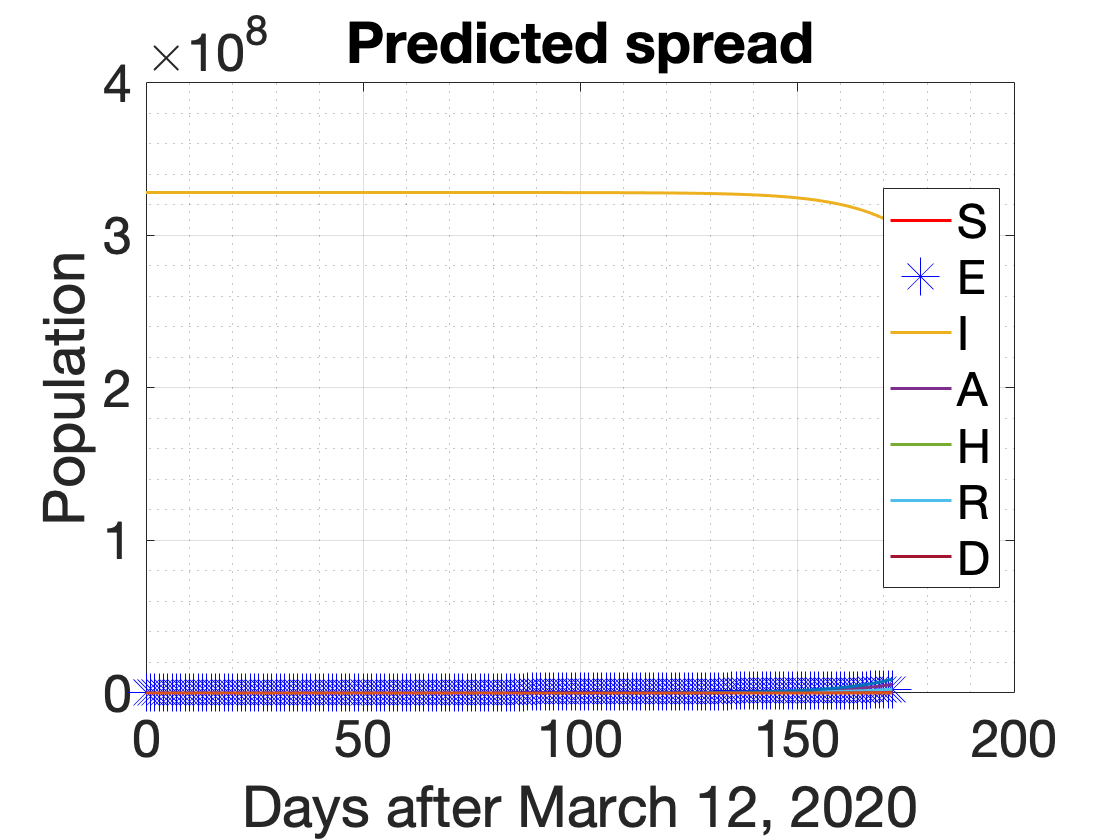

[t,y]= ode45(@(t,y)ode_radiation_updated(t,y,eps,.202),tspan,y0);
    
    plot(t,y,'LineWidth',1.5,'MarkerSize',18);
legend('S','E','I','A','H','R','D','Location','best')
xlabel('Days after March 12, 2020')
ylabel('Population')
title('Predicted spread')
grid on;
grid minor;
set(gca,'FontSize',26)

hold off;

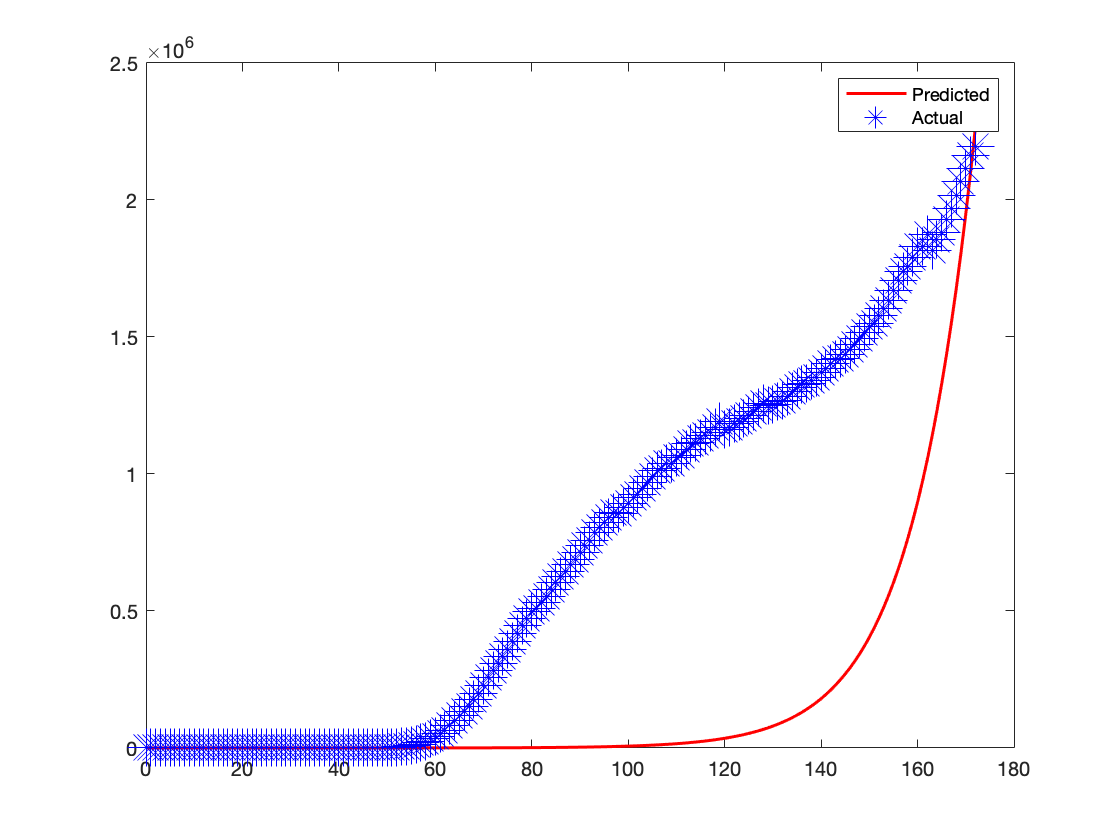


figure
plot(tspan, y(:,3), 'r-', 'LineWidth', 1.5, 'MarkerSize', 18);
hold on;
plot(tspan, actual_vals, 'b*', 'MarkerSize', 18);
legend('Predicted', 'Actual');